# UBC CPSC  302 Num Comp for Alg Problems, 2019W

# Assignment 1

### by [Bob Ghosh] #[42039157]

*Tips: Read the tips (italics) in the assignment below for a guide to get the most credit possible on this and future assignments.  Replace the [Preferred Name] and [Student Number] above. *

## Acknowledgments

You are welcome to work with other students on this assignment, but everything in this file must clearly be your own original work.  Complete the following section to recognize your collaborators on this assignment.


$$\underline{~~~~~~~~~~~~~~~~~~~~~\text{ Begin acknowledgments }~~~~~~~~~~~~~~~~~~~~~}$$


Thanks to [person] for [their contribution].

Thanks to [person] for [their contribution].

Other than the contributions above, this work is my own.

— [Your preferred name]


$$\underline{~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~}\\
~~~~~~~~~~~~~~~~~~~~~~\text{ End acknowledgments }$$


## Question 1(a)

Carry out a derivation analogous to that in Example 1.2 in the text [[AG](https://epubs-siam-org.ezproxy.library.ubc.ca/doi/book/10.1137/9780898719987)], using the expression 


$$\frac{f(x_0+h)-f(x_0-h)}{2h}$$


for approximating the first derivative $f'(x_0)$.  Show that the discretization error satisfies


$$f'(x_0) -\frac{f(x_0+h)-f(x_0-h)}{2h} \approx -\frac{h^2}6 f'''(x_0)$$


for $h$ small enough, when  $f'''(x_0) \neq 0$.  Thus, this error is $\mathcal{O} (h^2)$, meaning that it decreases like $h^2$ as $h$ is decreased.

### Answer 1(a)

Enter your solution in the space below.

*Tips: You may write your math in *[*LaTeX ($...$)*](https://www.mathworks.com/help/matlab/matlab_prog/insert-equations.html#bvak508)* or insert ****clear, legible**** images of hand-written math.  Your work shown should be logical and have no gaps. Don't just write down the final solution – show how you get to the solution.*


$$\underline{~~~~~~~~~~~~~~~~~~~~~\text{ Begin answer }~~~~~~~~~~~~~~~~~~~~~}$$


Given our case, we may assume that 'h' is small. Therefore, similar to **Example 1.2**, we can use $f(x_0 + h) = f(x_0)+hf'(x_0) + \frac{h^2}{2}f''(x_0)+ \frac{h^3}{6}f'''(x_0)+ \frac{h^4}{24}f''''(x_0)+\dots$ Similarly, we can write  $f(x_0 - h) = f(x_0 + (-h))$ = $f(x_0)-hf'(x_0) + \frac{(-h)^2}{2}f''(x_0)+ \frac{(-h)^3}{6}f'''(x_0)+ \frac{(-h)^4}{24}f''''(x_0)+\dots$ = $f(x_0)-hf'(x_0) + \frac{h^2}{2}f''(x_0)- \frac{h^3}{6}f'''(x_0)+ \frac{h^4}{24}f''''(x_0)-\dots$. Now, we have the values for $f(x_0 + h) \&  f(x_0-h)
$and we can use the formula to compute $\frac{f(x_0+h)-f(x_0-h)}{2h}$. 

Therefore, $f(x_0 + h) - f(x_0-h) = 2hf'(x_0)+\frac{2h^3}{6}f'''(x_0)+\frac{2h^5}{120}f'''''(x_0)+\dots$

and, $\frac{f(x_0+h)-f(x_0-h)}{2h} =  f'(x_0)+\frac{h^2}{6}f'''(x_0)+\frac{h^4}{120}f'''''(x_0)+\dots$

Finally, using what we derived above, we can write $f'(x_0) -\frac{f(x_0+h)-f(x_0-h)}{2h}$ as:

$f'(x_0) - \frac{f(x_0+h) - f(x_0-h)}{2h} = \frac{-h^2}{6}f'''(x_0) - [\frac{h^4}{120}f'''''(x_0)+\dots] \approx  \frac{-h^2}{6}f'''(x_0)$. As 'h' is small enough we can use the aforementioned approximation, and the discretization error satisfies it. Thus, this error is $\mathcal{O} (h^2)$, meaning that it decreases like $h^2$ as $h$ is decreased.


$$\underline{~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~}\\
~~~~~~~~~~~~~~~~~~~~~~\text{ End answer}$$


## Question 1(b)

Write a program to carry out similar calculations to those of Examples 1.2 and 1.3 using the above approximation.  Observe similarities and differences comparing your graph against that in Figure 1.3 of the text.

### Answer 1(b)

Enter your solution in the space below.

*Tips: Insert clear, functioning MATLAB code as necessary.  You may also insert non-functioning code snippets as "code examples".  Document your code clearly and effectively with comments (*`% This is a comment`*).  Any functions you write should be placed at the end of this script – add comments to point the reader to them.  Surround your code with explanatory text to make observations about the output of your code and justify your observations with theoretical knowledge. If possible, quantify your observations to further support your claims  (e.g. "By employing method X I was able to further reduce the error by 10%.")*


$$\underline{~~~~~~~~~~~~~~~~~~~~~\text{ Begin answer }~~~~~~~~~~~~~~~~~~~~~}$$


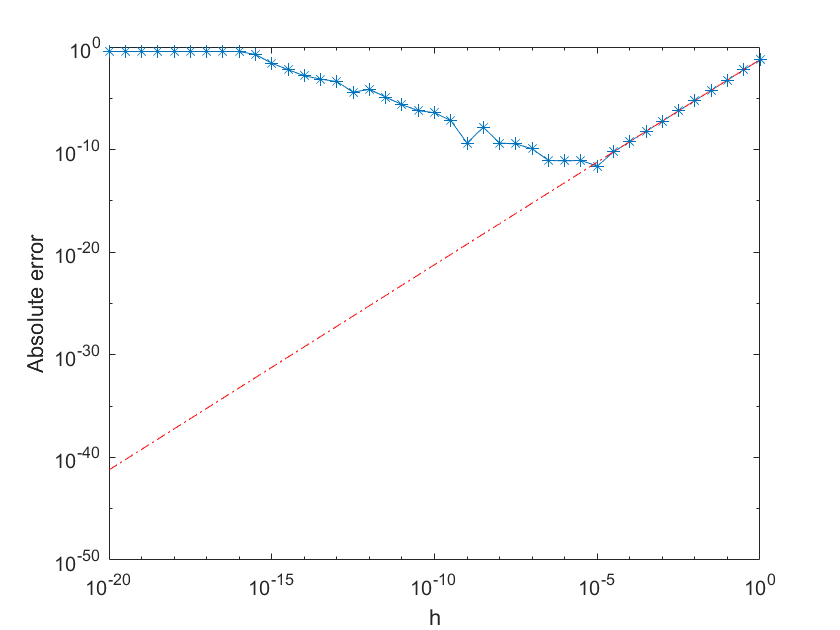

% Following the example 1.3 of the text, and using the same values.
x0 = 1.2; % value of interest
fp = cos(x0); % f prime
ftp = -cos(x0); % third prime of f
i = -20:0.5:0;
h = 10.^i;
err = abs (fp - (sin(x0+h) - sin(x0-h))./(2*h));
d_err = -ftp/6*(h.^2); % using the formula from part a
loglog (h, err,' -*');
hold on;
loglog (h, d_err, 'r-.');
xlabel('h')
ylabel('Absolute error')


$$\underline{~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~}\\
~~~~~~~~~~~~~~~~~~~~~~\text{ End answer}$$


## Question 2

Consider the problem of calculating the integral


$$u_n = \int_{0}^{1} \frac{x^n}{x+0.5} dx,$$


for the values $n = 0, 1, 2, \ldots, 50$.

## Question 2(a)

Derive a formula expressing $u_n$ in terms of $u_{n-1}$ exactly, i.e., without any discretization error, for any positive integer $n$. Your formula should look like

$u_n = a\cdot u_{n-1} + b$,

and your task is to find the scalars $a$ and $b$.

### Answer 2(a)

Enter your solution in the space below.

*Tips: Not all answer parts require MATLAB code.  In this part a short explanation and derivation is sufficient.  You may write your math in LaTeX or insert clear image(s) of handwritten equations.*


$$\underline{~~~~~~~~~~~~~~~~~~~~~\text{ Begin answer }~~~~~~~~~~~~~~~~~~~~~}$$



$$\underline{~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~}\\
~~~~~~~~~~~~~~~~~~~~~~\text{ End answer}$$


## Question 2(b)

Find an exact expression for $u_0$.  Then derive a stable algorithm for obtaining $u_1, u_2, \ldots , u_{50}$ in sequence.  Explain why your algorithm is stable.

### Answer 2(b)

Enter your solution in the space below.


$$\underline{~~~~~~~~~~~~~~~~~~~~~\text{ Begin answer }~~~~~~~~~~~~~~~~~~~~~}$$



$$\underline{~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~}\\
~~~~~~~~~~~~~~~~~~~~~~\text{ End answer}$$


## Question 2(c)

Write a short MATLAB code to calculate these 51 values, printing out $u_{50}$.  Your script should also print out the differences $u_n-u_{n-1}$, or alternatively, a warning in case that $u_n > u_{n-1}$ for some $n$.

[Note that since in the integral $0 \leq x \leq 1$, we have for any positive integer $n$ that $0 \leq x^n \leq x^{n-1}$, and therefore, 

$0 \leq u_n \leq u_{n-1} \leq \dots \leq u_0$.

Hence, if nothing goes wrong, you should obtain $u_n-u_{n-1} \leq 0$ for each $n$.]

### Answer 2(c)

Enter your solution in the space below.


$$\underline{~~~~~~~~~~~~~~~~~~~~~\text{ Begin answer }~~~~~~~~~~~~~~~~~~~~~}$$



$$\underline{~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~}\\
~~~~~~~~~~~~~~~~~~~~~~\text{ End answer}$$


## Functions

MATLAB requires all functions to be at the [end of the script](https://www.mathworks.com/help/matlab/matlab_prog/local-functions-in-scripts.html).  Enter functions you wrote for this assignment in the space below.

*Tips: You only need to complete this section if you developed and used your own MATLAB function(s) in your code above.  If you do define your own functions, organize your code; use indenting and reasonable variables (e.g. no unused variables or ambiguous names).  Document your code clearly and effectively with comments (*`% This is a comment`*).  Note the specific purpose of each function; indicate input requirements and output results.*


$$\underline{~~~~~~~~~~~~~~~~~~~~~\text{ Begin functions}~~~~~~~~~~~~~~~~~~~~~}$$



$$\underline{~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~}\\
~~~~~~~~~~~~~~~~~~~~~~\text{ End functions}$$
